clear; clc; close all;

digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', ...
    'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    "IncludeSubfolders", true, 'LabelSource', 'foldernames');

img = readimage(imds, 3000);
size(img)

ans =     28    28


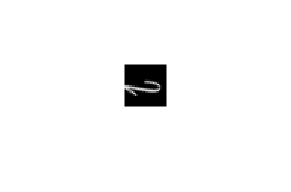

imshow(img)

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.6, 'randomized')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9005.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9006.png'
                               ... and 5997 more
                              }
                     Folders: {
                              ' ...\Matlab2023a\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 5997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

imdsValidation =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9003.png'
                               ... and 3997 more
                              }
                     Folders: {
                              ' ...\Matlab2023a\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 3997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
              

layers_G1 = [
    featureInputLayer(4032, "Normalization", "none")
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(6)
    softmaxLayer
    classificationLayer
    ]

layers_G1 =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         6 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

layers_G2 = {};
for i = 1:6
    layers = [
        featureInputLayer(4032, "Normalization", "none")
        fullyConnectedLayer(512)
        reluLayer
        fullyConnectedLayer(256)
        reluLayer
        fullyConnectedLayer(128)
        reluLayer
        fullyConnectedLayer(64)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(5)
        softmaxLayer
        classificationLayer
        ];
    layers_G2{i} = layers;
end
layers_G2{1}

ans =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         5 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

layers_G3 = {};
for i = 1:5
    layers = [
        featureInputLayer(4032, "Normalization", "none")
        fullyConnectedLayer(512)
        reluLayer
        fullyConnectedLayer(256)
        reluLayer
        fullyConnectedLayer(128)
        reluLayer
        fullyConnectedLayer(64)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(4)
        softmaxLayer
        classificationLayer
        ];
    layers_G3{i} = layers;
end
layers_G3{1}

ans =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         4 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironme

net = trainNetwork(imdsTrain, layers, options)

YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred==YValidation)/numel(YValidation)